This file is used to design custom Bezier curves for testing the table and creating demos for the project fair.

close all;

x1 = 24.03/100;
x2 = 45.7/100;
x3 = 69/100;
y = 49.58/100;

puck_positions = [x1 y; x3 y; x2 y+0.22; x2 y-0.21];

xcoeffs = [];
ycoeffs = [];
traj_durations = [];

## Compute Bezier curves

figure;
axis equal
hold on
viscircles(puck_positions,repmat(0.0675/2,size(puck_positions,1),1),'LineStyle','-','Color','black');
rectangle('position',[0 0 1 1])

xlim([-0.1 1.1])
ylim([-0.1 1.1])

### Section 1: Start

Starting point

q0 = [0.05;0.05];
v0 = [0;0];

End point

q3 = [0.46;0.5];
v3 = [2.5;2];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q0(1), q0(2), 'b.', 'markersize', 15);
plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 2: up to top

q0 = q3;
v0 = v3;

q3 = [0.46;0.83];
v3 = [-3;0];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 3: back to center

q0 = q3;
v0 = v3;

q3 = [0.46;0.5];
v3 = [2.5;-2];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q0(1), q0(2), 'b.', 'markersize', 15);
plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 4: down to bottom

q0 = q3;
v0 = v3;

q3 = [0.46;0.17];
v3 = [-3;0];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 5: back to center

q0 = q3;
v0 = v3;

q3 = [0.46;0.5];
v3 = [2;2.5];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q0(1), q0(2), 'b.', 'markersize', 15);
plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 6: to right side

q0 = q3;
v0 = v3;

q3 = [0.79;0.5];
v3 = [0;-3];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 7: back to center

q0 = q3;
v0 = v3;

q3 = [0.46;0.5];
v3 = [-2;2.5];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 8: to left

q0 = q3;
v0 = v3;

q3 = [0.13;0.5];
v3 = [0;-3.5];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

xlabel("X Position (m)", FontSize=15)
ylabel("Y Position (m)", FontSize=15)

### Section 9: back to center

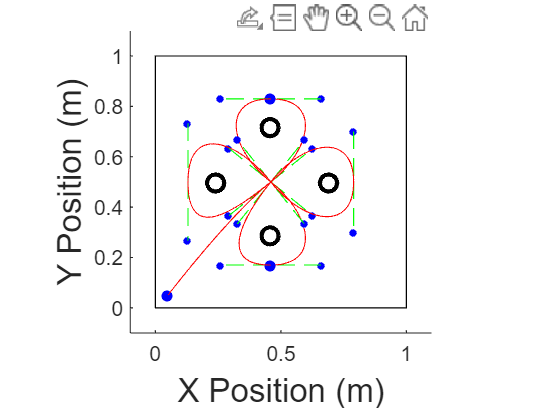

q0 = q3;
v0 = v3;

q3 = [0.46;0.5];
v3 = [2.5;2];
traj_durations(end+1) = 0.2;

q1 = q0 + v0.*traj_durations(end)/3;
q2 = q3 - v3.*traj_durations(end)/3;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

xcoeffs(end+1,:) = fliplr([3*q1(1) - q0(1) - 3*q2(1) + q3(1), 3*q0(1) - 6*q1(1) + 3*q2(1), 3*q1(1)- 3*q0(1), q0(1)]);
ycoeffs(end+1,:) = fliplr([3*q1(2) - q0(2) - 3*q2(2) + q3(2), 3*q0(2) - 6*q1(2) + 3*q2(2), 3*q1(2)- 3*q0(2), q0(2)]);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'--g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'--g')

plot(xy1(1,:), xy1(2,:), '-r')

## Calculate motion data from Bezier curves

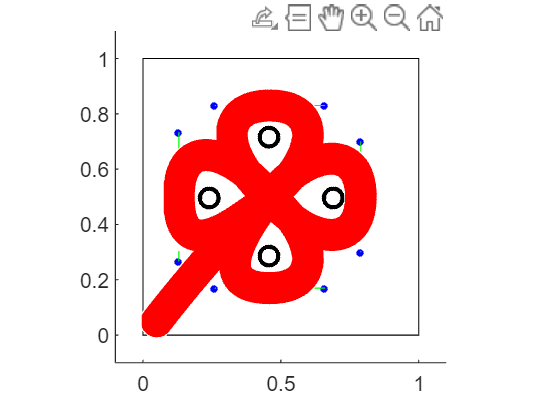

x_pos = [];
y_pos = [];
x_vel = [];
y_vel = [];
x_acc = [];
y_acc = [];
x_jerk = [];
y_jerk = [];

for n = 1:size(xcoeffs,1)
    u = 0:0.01:1; % TODO: Scale by the path duration

    x_pos_new = xcoeffs(n,1) + xcoeffs(n,2)*u + xcoeffs(n,3)*u.^2 + xcoeffs(n,4)*u.^3;
    y_pos_new = ycoeffs(n,1) + ycoeffs(n,2)*u + ycoeffs(n,3)*u.^2 + ycoeffs(n,4)*u.^3;
    x_pos = [x_pos, x_pos_new];
    y_pos = [y_pos, y_pos_new];
    
    x_vel_new = 1/traj_durations(n)*(xcoeffs(n,2) + xcoeffs(n,3)*2.*u + xcoeffs(n,4)*3*u.^2);
    y_vel_new = 1/traj_durations(n)*(ycoeffs(n,2) + ycoeffs(n,3)*2.*u + ycoeffs(n,4)*3*u.^2);
    x_vel = [x_vel, x_vel_new];
    y_vel = [y_vel, y_vel_new];
    
    x_acc_new = 1/traj_durations(n)^2*(xcoeffs(n,3)*2 + xcoeffs(n,4)*6*u);
    y_acc_new = 1/traj_durations(n)^2*(ycoeffs(n,3)*2 + ycoeffs(n,4)*6*u);
    x_acc = [x_acc, x_acc_new];
    y_acc = [y_acc, y_acc_new];
    
    x_jerk_new = 1/traj_durations(n)^3*xcoeffs(n,4)*6*ones(1,length(u));
    y_jerk_new = 1/traj_durations(n)^3*ycoeffs(n,4)*6*ones(1,length(u));
    x_jerk = [x_jerk, x_jerk_new];
    y_jerk = [y_jerk, y_jerk_new];
end

t = 0:0.01:0.01*(length(x_pos)-1);

viscircles([x_pos',y_pos'],repmat(0.05,length(x_pos),1),'LineStyle','-','Color','red');

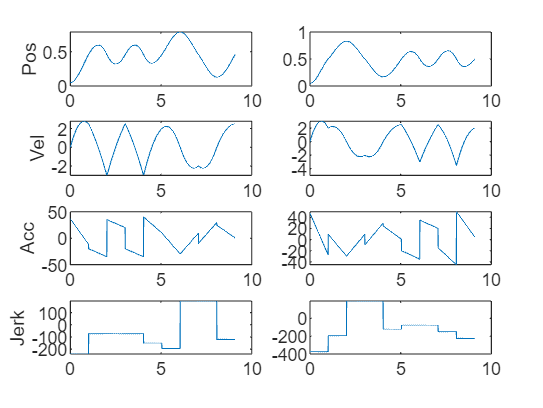


figure;
subplot(4,2,1)
plot(t,x_pos)
ylabel('Pos')
subplot(4,2,2)
plot(t,y_pos)
subplot(4,2,3)
plot(t,x_vel)
ylabel('Vel')
subplot(4,2,4)
plot(t,y_vel)
subplot(4,2,5)
plot(t,x_acc)
ylabel('Acc')
subplot(4,2,6)
plot(t,y_acc)
subplot(4,2,7)
plot(t,x_jerk)
ylabel('Jerk')
subplot(4,2,8)
plot(t,y_jerk)

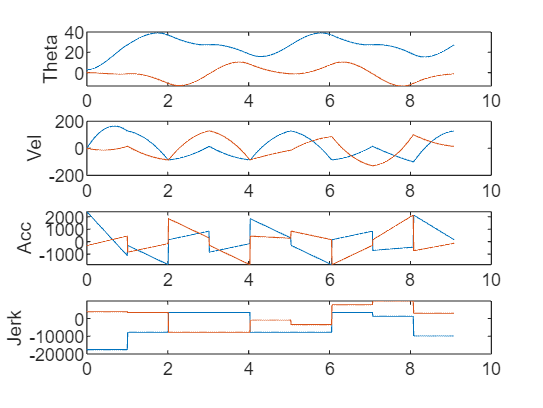

theta_rad_to_xy_cm = [1,1;1,-1]*3.5/2;
xy_cm_to_theta_rad = inv(theta_rad_to_xy_cm);

thetas = xy_cm_to_theta_rad * 100 * [x_pos; y_pos];
theta_vel = xy_cm_to_theta_rad * 100 * [x_vel; y_vel];
theta_acc = xy_cm_to_theta_rad * 100 * [x_acc; y_acc];
theta_jerk = xy_cm_to_theta_rad * 100 * [x_jerk; y_jerk];

figure;
subplot(4,1,1)
plot(t,thetas)
ylabel('Theta')
subplot(4,1,2)
plot(t,theta_vel)
ylabel('Vel')
subplot(4,1,3)
plot(t,theta_acc)
ylabel('Acc')
subplot(4,1,4)
plot(t,theta_jerk)
ylabel('Jerk')

## Validate trajectory using feed forward gains

If the Simulink model requires above 24V to track the desired trajectory, the real robot will probably not be able to keep up.

### To run this section:

- Open analysis.mlx in the Simulink repository. Run the analysis.mlx livescript up until at least the "Controller Parameters" section. This will generate the feedforward gain matrix Kff.    

% left_feed_forward = 100/24 * (Kff{1,1} * [theta_jerk(1,:); theta_acc(1,:); theta_vel(1,:); thetas(1,:)]) ...
%                     + 100/24 * (Kff{1,2} * [theta_jerk(2,:); theta_acc(2,:); theta_vel(2,:); thetas(2,:)]);
% 
% right_feed_forward = 100/24 * (Kff{2,1} * [theta_jerk(1,:); theta_acc(1,:); theta_vel(1,:); thetas(1,:)]) ...
%                     + 100/24 * (Kff{2,2} * [theta_jerk(2,:); theta_acc(2,:); theta_vel(2,:); thetas(2,:)]);
% 
% figure;
% hold on
% plot(t,left_feed_forward)
% plot(t,right_feed_forward)
% yline([-100,100],'--')
% xlabel('Time (s)')
% ylabel('PWM (-100 to 100)')
% ylim([-110 110])

## Generate C++ code to realize these trajectory parameters

t_str = 'float traj_durations[] = {';

for n = 1:length(traj_durations)
    t_str = [t_str, num2str(traj_durations(n))];
    if n < length(traj_durations)
        t_str(end+1) = ',';
    end
end

t_str = [t_str, '};'];

x_str = ['array<array<float, 4>, ',num2str(size(xcoeffs,1)),'> x_traj_coeffs = {{'];
y_str = ['array<array<float, 4>, ',num2str(size(xcoeffs,1)),'> y_traj_coeffs = {{'];

for ii = 1:size(xcoeffs,1)
    x_str(end+1) = '{';
    y_str(end+1) = '{';

    for jj = 1:size(xcoeffs,2)
        x_str = [x_str, num2str(xcoeffs(ii,jj))];
        y_str = [y_str, num2str(ycoeffs(ii,jj))];
        if jj < size(xcoeffs,2)
            x_str(end+1) = ',';
            y_str(end+1) = ',';
        end
    end
    x_str(end+1) = '}';
    y_str(end+1) = '}';

    if ii < size(xcoeffs,1)
        x_str(end+1) = ',';
        y_str(end+1) = ',';
    end
end

x_str = [x_str, '}};'];
y_str = [y_str, '}};'];


fprintf([t_str, '\n', x_str, '\n', y_str])

float traj_durations[] = {0.2,0.2,0.2,0.2,0.2,0.2,0.2,0.2,0.2};
array<array<float, 4>, 9> x_traj_coeffs = {{{0.05,0,0.73,-0.32},{0.46,0.5,-0.4,-0.1},{0.46,-0.6,0.7,-0.1},{0.46,0.5,-0.4,-0.1},{0.46,-0.6,0.8,-0.2},{0.46,0.4,0.19,-0.26},{0.79,0,-0.59,0.26},{0.46,-0.4,-0.19,0.26},{0.13,0,0.49,-0.16}}};
array<array<float, 4>, 9> y_traj_coeffs = {{{0.05,0,0.95,-0.5},{0.5,0.4,0.19,-0.26},{0.83,0,-0.59,0.26},{0.5,-0.4,-0.19,0.26},{0.17,0,0.49,-0.16},{0.5,0.5,-0.4,-0.1},{0.5,-0.6,0.7,-0.1},{0.5,0.5,-0.3,-0.2},{0.5,-0.7,1,-0.3}}};